% 同一通道，每一个时间点，多种刺激之间的重复测量ANOVA

% % data path
data_path = 'D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared';

% 定义一个对象用于存放不同marker信息
% 'CS+：112'
% 'GS1：113'
% 'GS2：114'
% 'GS3：115'
% 'GS4：116'
% 'GS5：117'
% 'GS6：118'
% 'GS7：119'
% 'GS8：120'
% 'CS-：121'
cond = {'112','113','114','115','116','117','118','119','120','121'};

% 将每个被试平均后的数据【分不同条件】合成一个数据集
for i = 1:4
    try
        % 拼接被试的文件名
        data_name = ['sub',num2str(i),'.set'];
        % 导入该被试数据
        EEG = pop_loadset('filename',data_name,'filepath',data_path);
        % 检查EEG数据是否完好
        EEG = eeg_checkset(EEG);
        for j = 1: length(cond)% 对于每个条件下的tiral
            EEG_new = pop_epoch(EEG,cond(j),[-1,2],'newname','sub_cond_lv_data','epochinfo','yes');
            EEG_new = eeg_checkset(EEG_new);
            % 基线矫正
            EEG_new = pop_rmbase(EEG_new,[-1000 0]);
            EEG_new = eeg_checkset(EEG_new);
            % EEG_new.data是一个三维数据集：channel × timepoint × trial
            % 做trial水平上的均值，降维，得到二维数据集，然后添加被试变量i，条件变量j，组成四维数据集
            % EEG_avg：subject × condition × channel × timepoint
            EEG_avg(i,j,:,:) = squeeze(mean(EEG_new.data,3));
        end
    catch ME
    end
end

pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub1.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():40 epochs selected
Epoching...
pop_epoch():40 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():15 epochs selected
Epoching...
pop_epoch():15 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():16 epochs selected
Epoching...
pop_epoch():16 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():15 epochs selected
Epoching...
pop_epoch():15 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():13 epochs selected
Epoching...
pop_epoch():13 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():15 epochs selected
Epoching...
pop_epoch():15 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():36 epochs selected
Epoching...
pop_epoch():36 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub2.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():20 epochs selected
Epoching...
pop_epoch():20 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():13 epochs selected
Epoching...
pop_epoch():13 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():10 epochs selected
Epoching...
pop_epoch():10 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():9 epochs selected
Epoching...
pop_epoch():9 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():18 epochs selected
Epoching...
pop_epoch():18 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub3.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():15 epochs selected
Epoching...
pop_epoch():15 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():11 epochs selected
Epoching...
pop_epoch():11 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():9 epochs selected
Epoching...
pop_epoch():9 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():10 epochs selected
Epoching...
pop_epoch():10 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():6 epochs selected
Epoching...
pop_epoch():6 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():9 epochs selected
Epoching...
pop_epoch():9 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():15 epochs selected
Epoching...
pop_epoch():15 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub4.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():19 epochs selected
Epoching...
pop_epoch():19 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():4 epochs selected
Epoching...
pop_epoch():4 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():4 epochs selected
Epoching...
pop_epoch():4 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():10 epochs selected
Epoching...
pop_epoch():10 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():9 epochs selected
Epoching...
pop_epoch():9 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():11 epochs selected
Epoching...
pop_epoch():11 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():23 epochs selected
Epoching...
pop_epoch():23 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


% 选择一个感兴趣的电极点（以AF4为例）
data_test = squeeze(EEG_avg(:,:,5,:));

% 对于每一个时间点：
for i = 1:size(data_test,3)
    % 提取所有被试该时间点的数据
    data_anova = squeeze(data_test(:,:,i));
    % 在第i个时间点下进行方差分析
    [p,table] = anova_rm(data_anova,'off');
    % 汇总p值
    p_anova(i) = p(1); % 我也不知道为什么是p(1)，有两个p值，教程中取第一个
end

clear i j p EEG_new data_anova

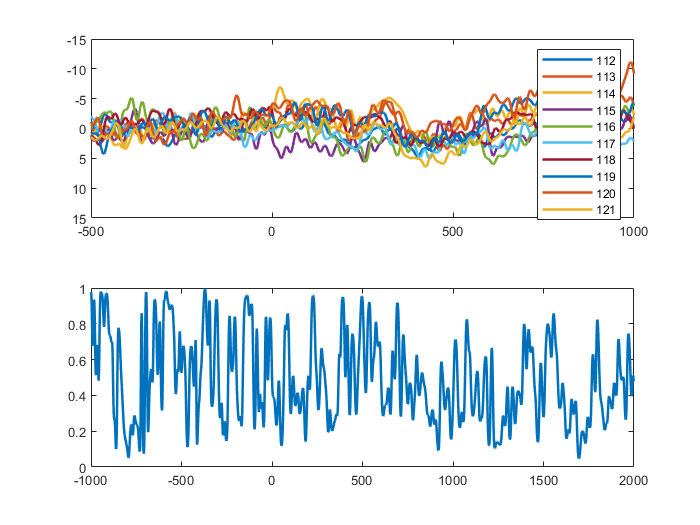

% 绘图
figure;
% 十个刺激的erp图
subplot(211);
plot(EEG.times,squeeze(mean(data_test,1)),'LineWidth',1.5);
set(gca,'YDir','reverse');
axis([-500 1000 -15 15]);
legend(cond);

subplot(212);
plot(EEG.times,p_anova,"LineWidth",1.5);